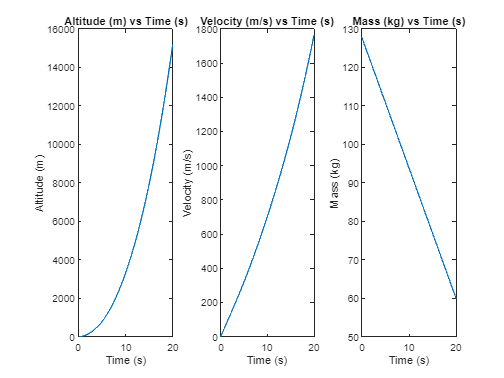

if ~exist('S', 'var')
    denebsim
end

if ~exist('Deneb', 'var')
    ROCKET
end

plotPhase(T_Powered, S_Powered)

EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for theta, are you doing subsonic?
EROORR!!!! no solultion for m2, are you doing subsonic?


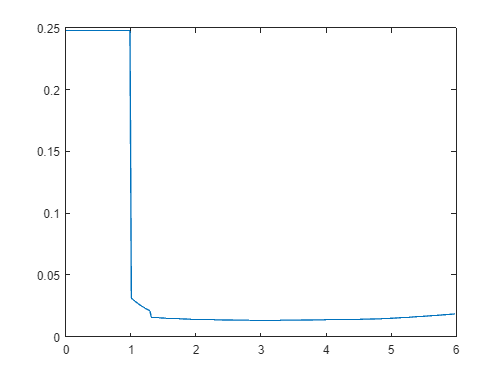

ans =        NaN    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478    0.2478


dragAnalysis(T_Powered, S_Powered, Deneb.DIAMETER^2*pi/4, Deneb)

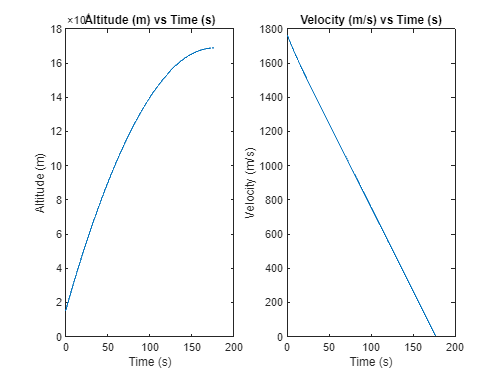

plotPhase(T_Ballistic, S_Ballistic)

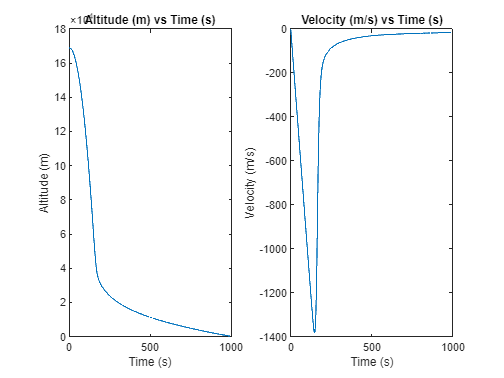

plotPhase(T_Drogue, S_Drogue)

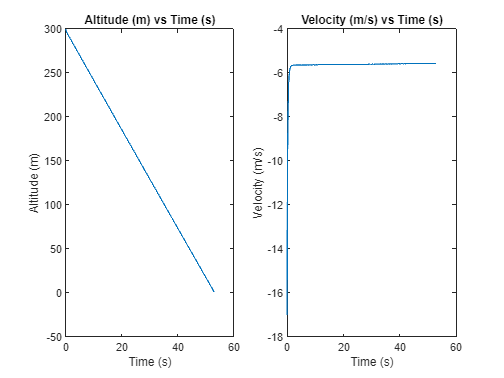

plotPhase(T_Main, S_Main)

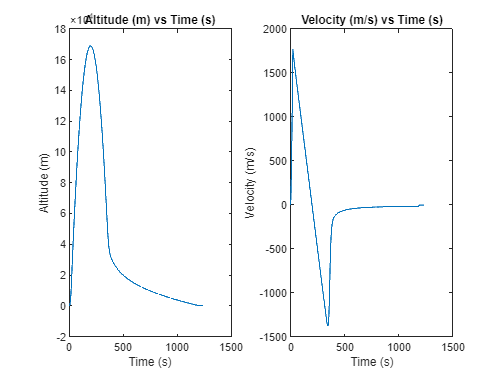

plotPhase(T, S)

function plotPhase(T, S)
    Ssize = size(S);
    svarcount = Ssize(2);

    figure

    svars = ["Altitude (m)", "Velocity (m/s)", "Mass (kg)"];
    for i=1:svarcount
        subplot(1,svarcount,i)
        plot(T,S(:,i))
        title(svars(i)+" vs Time (s)")
        xlabel("Time (s)")
        ylabel(svars(i))
    end

end

function C_D = dragAnalysis(T, S, refA, Deneb)
    C_D = [];
    for i=S'
        [T_, a, P, rho] = atmosisa(i(1), "extended","on", "action","None");
        if i(2)/a > 1
            Fd = SonicSkinDrag(i(1), i(2), Deneb);
        else
            Fd = SubSonicSkinDrag(i(1), i(2), Deneb);
        end

        C_D(end+1) = 2*Fd/refA/rho/(i(2)^2);
    end
    figure
    plot(calcMach(S), C_D)
end

function mach = calcMach(S)
    mach = [];
    for i=S'
        [T_, a, P, rho] = atmosisa(i(1), "extended","on", "action","None");
        mach(end+1) = i(2)/a;
    end
end